# basic_waypoints

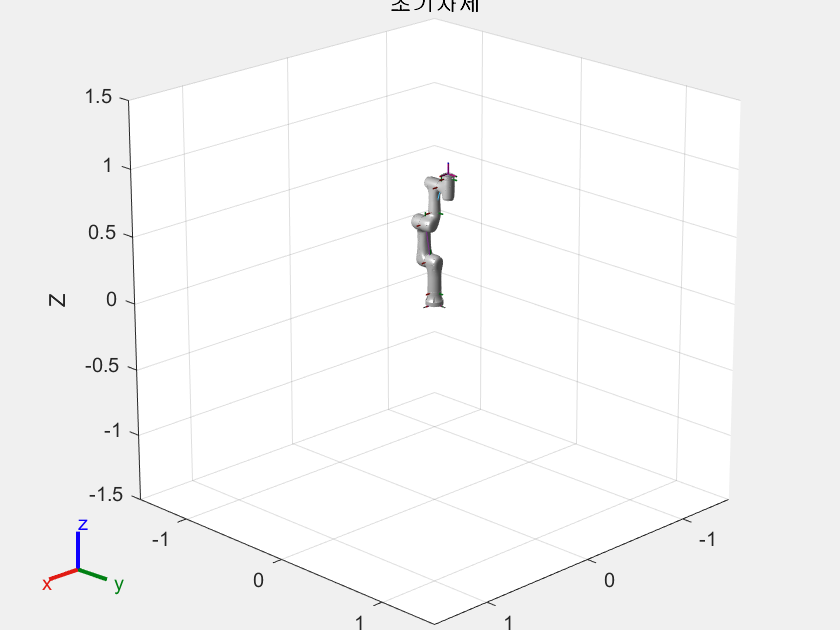

% 1. 로봇 로딩
urdfPath = "C:\Users\변재형\Documents\MATLAB\Nuri3s\nuri3s_urdf\nuri3s_matlab\nuri3s.urdf";
robot = importrobot(urdfPath);
robot.DataFormat = 'row';
robot.Gravity = [0 0 -9.81];
endEffector = 'tcp';

show(robot); view(135,20); title('초기자세');

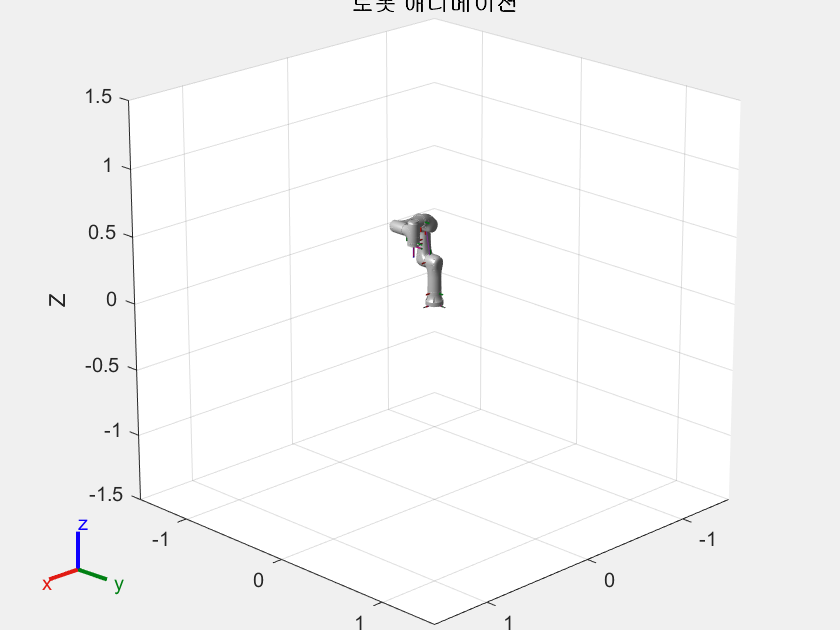


% 2. 시작 자세 qe (사진 기준)
qe = [0 0 -1.57 0 -1.57 0];  % 6x1

% 3. 1번 조인트만 회전시키며 원형 궤적 생성
N = 100;            % 샘플 수
T_total = 10;       % 총 시간
t = linspace(0, T_total, N);
theta = linspace(0, 2*pi, N);   % 0도~360도 회전

q_traj = repmat(qe(:), 1, N);   % 모든 조인트는 qe로 고정
q_traj(1, :) = theta;           % 1번 조인트만 회전시킴

% 4. 말단 궤적 추적용 위치 추출
ee_pos = zeros(3, N);
for i = 1:N
    T = getTransform(robot, q_traj(:,i)', endEffector);
    ee_pos(:,i) = tform2trvec(T)';
end

% === Figure 1: 로봇만 표시 ===
figure(1); clf;
show(robot, q_traj(:,1)', 'PreservePlot', false);
view(135,20); grid on; title('로봇 애니메이션');

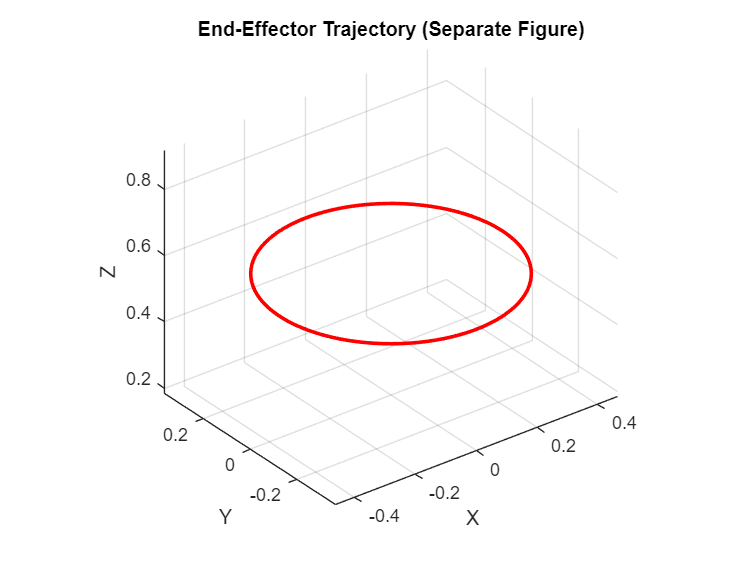

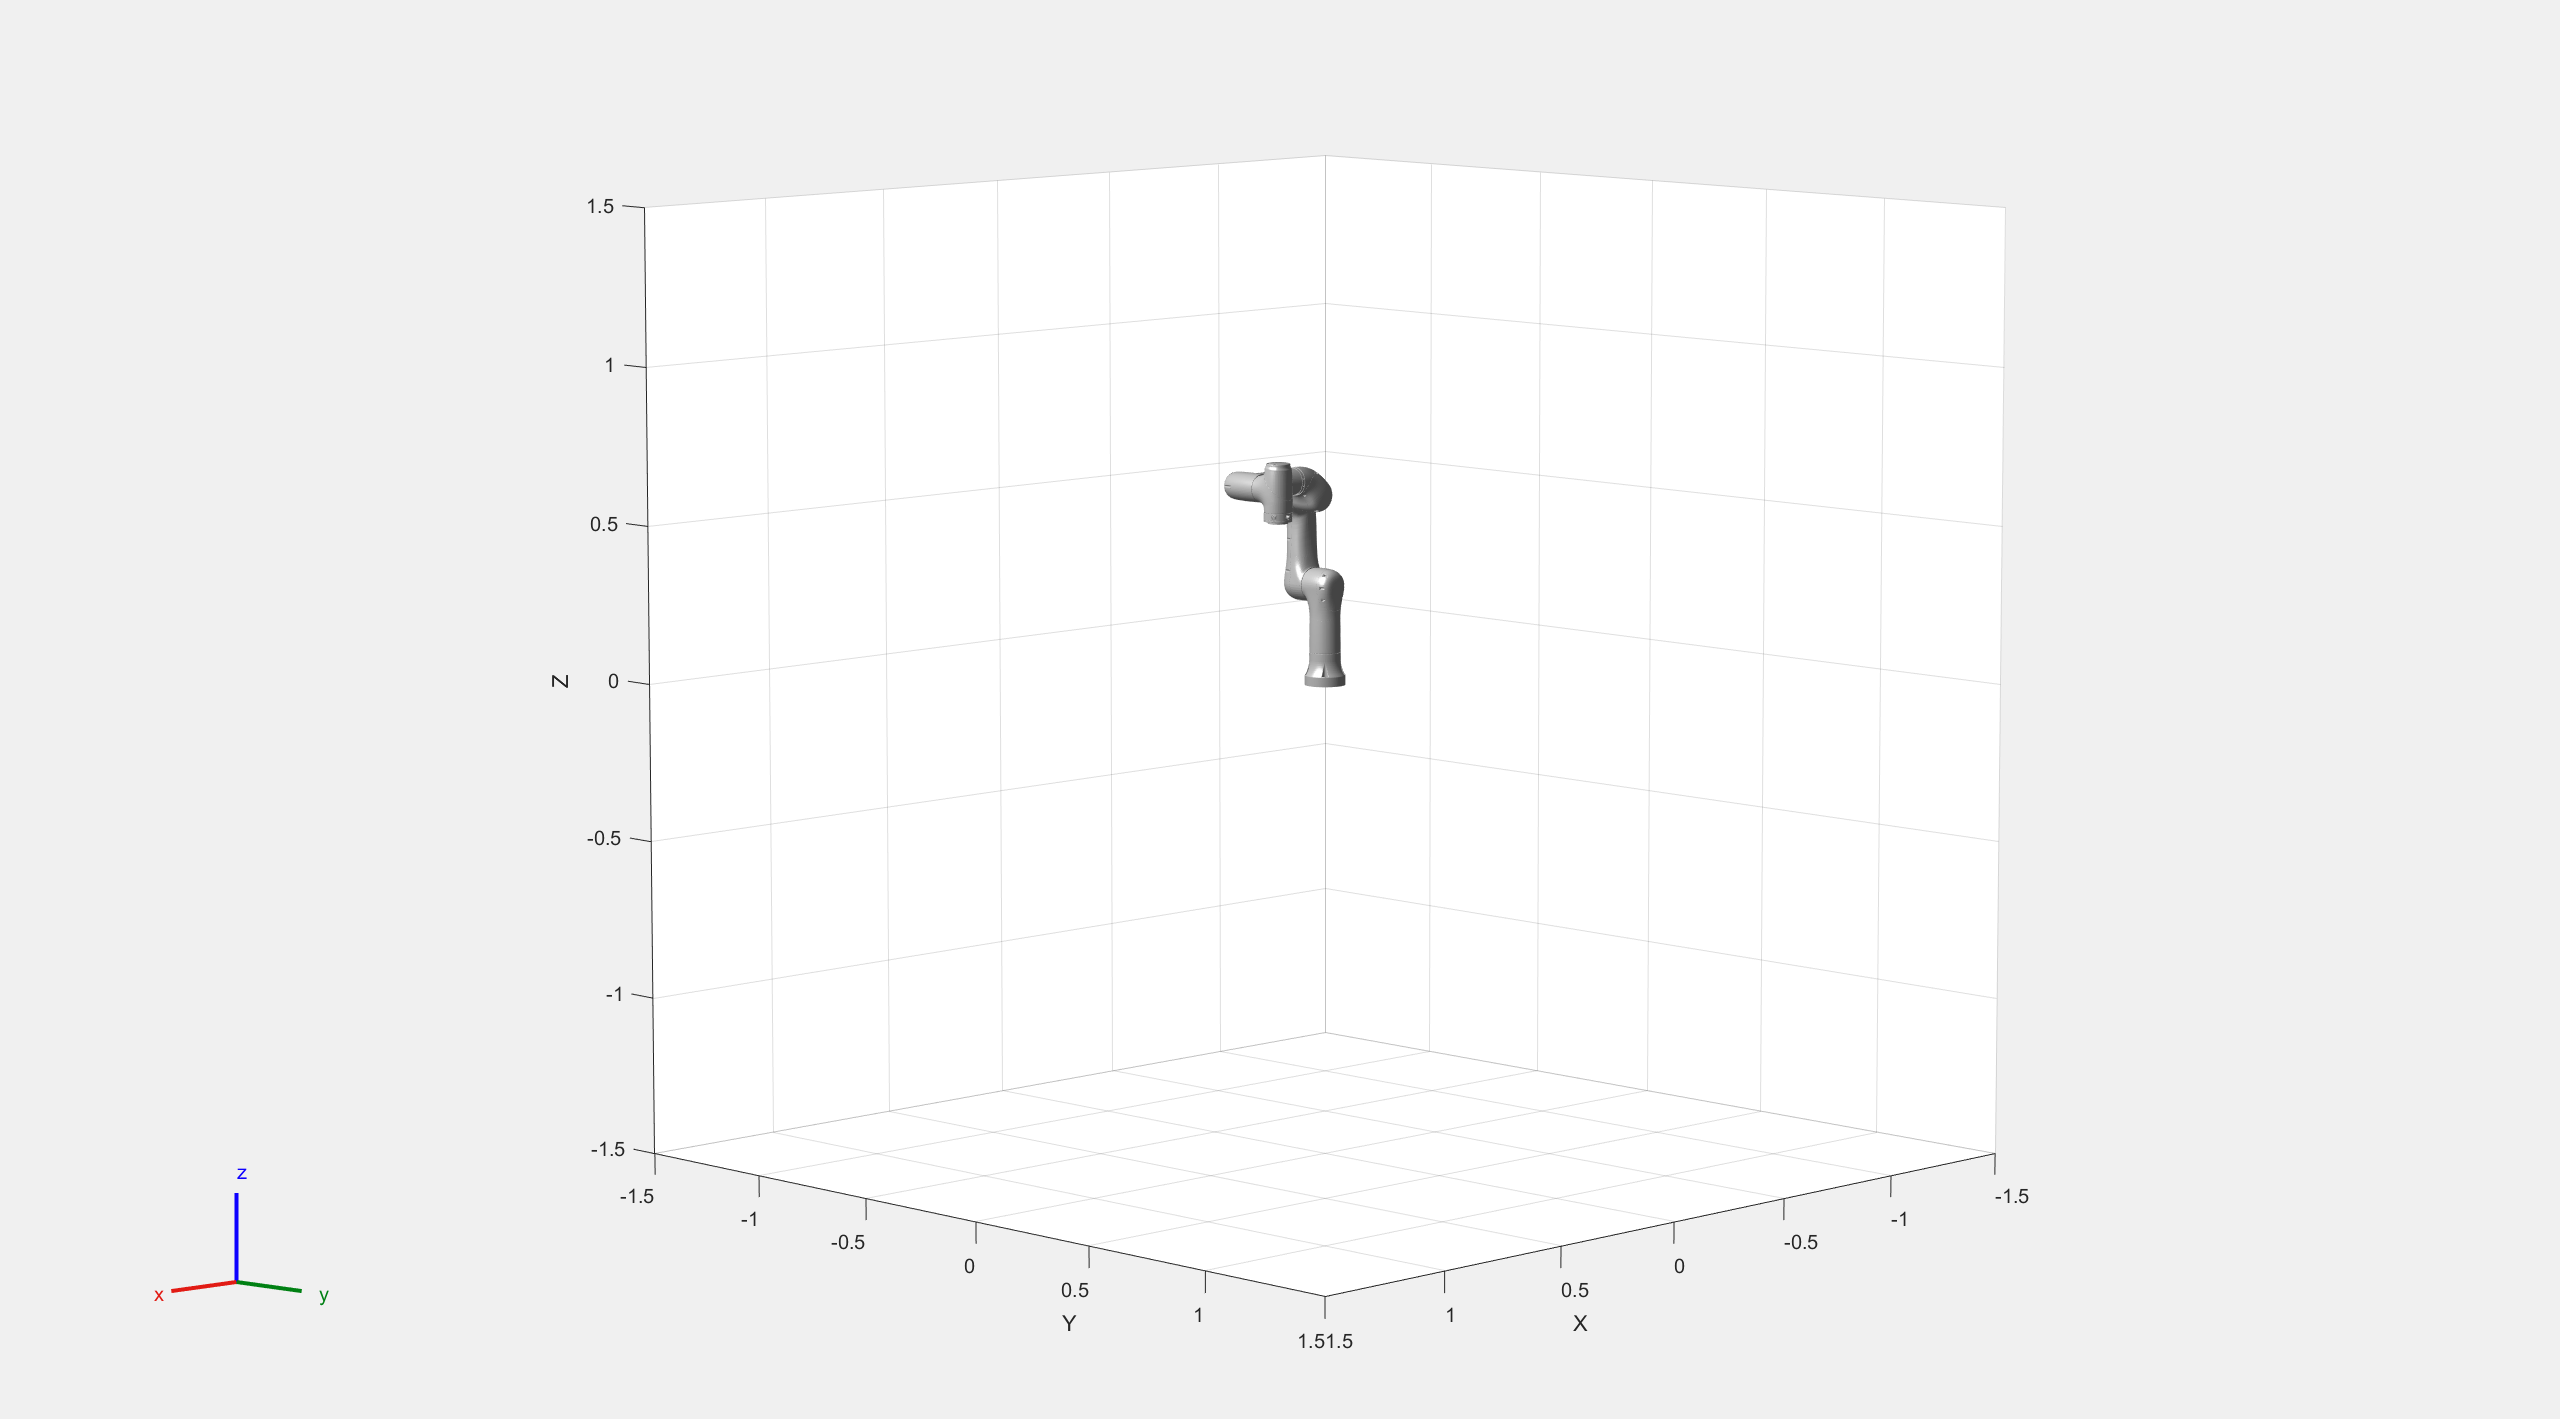


% === Figure 2: 궤적만 표시 ===
figure(2); clf;
xlabel('X'); ylabel('Y'); zlabel('Z');
grid on; axis equal;
title('End-Effector Trajectory (Separate Figure)');
view(3);
hold on;

% 빨간 선 궤적 초기화
trajLine = plot3(NaN, NaN, NaN, 'r-', 'LineWidth', 2);
xdata = []; ydata = []; zdata = [];

% === 애니메이션 루프 ===
for i = 1:N
    % Figure 1: 로봇
    figure(1);
    show(robot, q_traj(:,i)', 'PreservePlot', false, 'Frames', 'off');
    
    % Figure 2: 궤적 누적
    xdata(end+1) = ee_pos(1,i);
    ydata(end+1) = ee_pos(2,i);
    zdata(end+1) = ee_pos(3,i);
    
    figure(2);
    set(trajLine, 'XData', xdata, 'YData', ydata, 'ZData', zdata);
    
    drawnow limitrate;
end

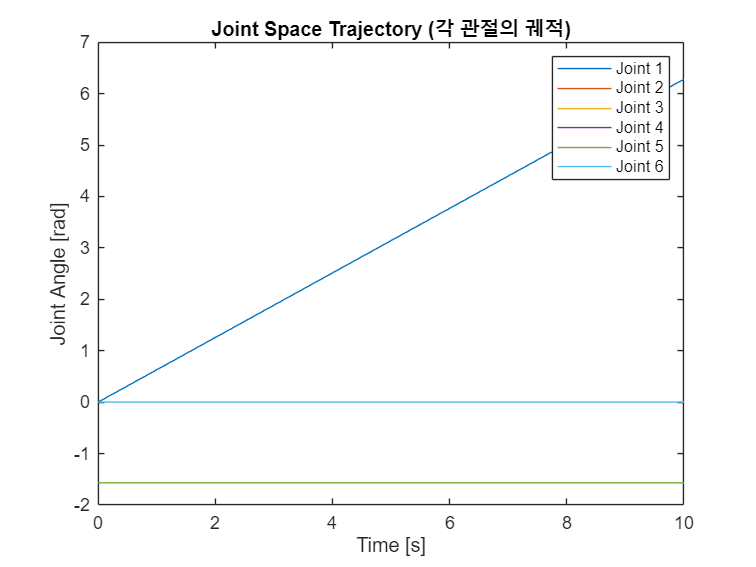


% ----- 5. 결과 Joint Trajectory 시각화 -----
figure;
plot(t, q_traj');
xlabel('Time [s]');
ylabel('Joint Angle [rad]');
title('Joint Space Trajectory (각 관절의 궤적)');
legend(arrayfun(@(i) sprintf('Joint %d', i), 1:size(q_traj,1), 'UniformOutput', false));


% 7. Joint Trajectory 저장
waypoints = q_traj;
timepoints = t;
save('nuri3s_basecircle_q1only.mat', 'waypoints', 'timepoints');
disp('저장 완료: nuri3s_basecircle_q1only.mat');

저장 완료: nuri3s_basecircle_q1only.mat


# 실제 원 경로만 그리기(바로 그려줌)

%%%%%%%%%%%%%%%%%%%%%%%%%%%% 수정할 부분 %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
load("q_waypoints_DOB_Gain1.mat")

다음 사용 중 오류가 발생함: load
파일 또는 디렉터리 'q_waypoints_DOB_Gain1.mat'을(를) 찾을 수 없습니다.


% 2. 변수 설정
q_vals = q_waypoints_DOB_Gain1; 
%%%%%%%%%%%%%%%%%%%%%%%%%%%% 수정할 부분 %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


endEffector = 'tcp';          % 말단 링크 이름
N = size(q_vals, 1);
ee_pos = zeros(3, N);         % 말단 위치 저장 공간

% 3. FK 계산 (q → 위치)
for i = 1:N
    T = getTransform(robot, q_vals(i,:), endEffector);
    ee_pos(:,i) = tform2trvec(T)';
end

% 4. 3D 원 궤적 플롯
figure;
plot3(ee_pos(1,:), ee_pos(2,:), ee_pos(3,:), 'b-', 'LineWidth', 2);
xlabel('X [m]'); ylabel('Y [m]'); zlabel('Z [m]');
title('Simulink 기반 말단 이펙터의 3D 궤적');
grid on; axis equal;
view(135, 30);  % 보기 각도 조정 (자유롭게 변경 가능)
xlim([-0.4 0.4])
ylim([-0.4 0.4])
zlim([0 0.997])
view([215.377 62.400])

# 로봇 제어기 원 궤적 애니매이션 (시간이 오래걸림)

% 초기화
xdata = []; ydata = []; zdata = [];

% 1번 figure: 로봇 초기화
figure(1);
show(robot, q_vals(1,:), 'PreservePlot', false, 'Frames', 'off');
view(135,30);
title('움직이는 로봇');
grid on;

% 2번 figure: 궤적 초기화
figure(2);
trajLine = plot3(0,0,0,'b-','LineWidth',2);  % 초기 plot
xlabel('X'); ylabel('Y'); zlabel('Z');
title('Simulink 기반 말단 궤적 애니메이션');
axis equal; grid on;
view(135,30);
xlim([min(ee_pos(1,:)) max(ee_pos(1,:))]);
ylim([min(ee_pos(2,:)) max(ee_pos(2,:))]);
zlim([min(ee_pos(3,:)) max(ee_pos(3,:))]);
xlim([-0.4 0.4])
ylim([-0.4 0.4])
zlim([0 0.997])
view([215.377 62.400])

% === 애니메이션 루프 ===
for i = 1:N
    % Figure 1: 로봇 움직임
    figure(1);
    show(robot, q_vals(i,:), 'PreservePlot', false, 'Frames', 'off');
    title(sprintf('로봇 동작 (Step %d/%d)', i, N));
    drawnow limitrate;

    % Figure 2: 궤적 누적
    xdata(end+1) = ee_pos(1,i);
    ydata(end+1) = ee_pos(2,i);
    zdata(end+1) = ee_pos(3,i);

    figure(2);
    set(trajLine, 'XData', xdata, 'YData', ydata, 'ZData', zdata);
    drawnow limitrate;
end

# 원 궤적 한번에 그리기( 한번에 빨간색( 기본), 파란색(제어기) )


% 2. 데이터 로드
load("nuri3s_basecircle_q1only.mat");      % 수정 x

%%%%%%%%%%%%%%%%%%%%%%%%%%%% 수정할 부분 %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
load("q_waypoints_DOB_Gain1.mat");  % 변수: q_waypointsHome_sim (N1 x 6)

%%%%%%%%%%%%%%%%%%%%%%%%%%%% 수정할 부분 %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


% 크기 통일 (모두 [N x 6] 형태로)
%%%%%%%%%%%%%%%%%%%%%%%%%%%% 수정할 부분 %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
q1 = q_waypoints_DOB_Gain1;
%%%%%%%%%%%%%%%%%%%%%%%%%%%% 수정할 부분 %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

q2 = waypoints;
if size(q2, 1) == 6
    q2 = q2';
end

% 3. 말단 이펙터 위치 계산 (Forward Kinematics)
N1 = size(q1, 1);
N2 = size(q2, 1);
ee_pos1 = zeros(3, N1);  % 제어기 궤적
ee_pos2 = zeros(3, N2);  % 기본 원 궤적

for i = 1:N1
    T = getTransform(robot, q1(i,:), endEffector);
    ee_pos1(:,i) = tform2trvec(T)';
end

for i = 1:N2
    T = getTransform(robot, q2(i,:), endEffector);
    ee_pos2(:,i) = tform2trvec(T)';
end

% 4. 결과 플롯
figure;
plot3(ee_pos1(1,:), ee_pos1(2,:), ee_pos1(3,:), 'b-', 'LineWidth', 2); hold on;
plot3(ee_pos2(1,:), ee_pos2(2,:), ee_pos2(3,:), 'r--', 'LineWidth', 2);
grid on; axis equal;
xlabel('X [m]'); ylabel('Y [m]'); zlabel('Z [m]');
title('End-Effector 궤적 비교');
legend('Simulink 제어기 궤적', '기본 원 궤적');

xlim([-1 1])
ylim([-1 1])
zlim([0 0.997])
view([215.377 62.400])


# q 값 비교 분석 ( 각 관절 값 ) 


% 1. 데이터 불러오기
%%%%%%%%%%%%%%%%%%%%%%%%%%%% 수정할 부분 %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
load("nuri3s_basecircle_q1only.mat"); % <- 얘는 고정 reference waypoints임

load("q_waypointsHome_DOB_sim.mat"); % <- 얘만 제어기에 따라 수정

q_basic = waypoints; % <- 얘도 고정

q_dob = q_waypointsHome_DOB_sim; % <- 얘도 제어기에 따라 수정

%%%%%%%%%%%%%%%%%%%%%%%%%%%% 수정할 부분 %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% 전치
if size(q_basic, 1) == 6
    q_basic = q_basic';
end

% 길이 파악
N_dob = size(q_dob,1);
N_basic = size(q_basic,1);
t_dob = linspace(0, 10, N_dob);
t_basic = linspace(0, 10, N_basic);

% 2. 보간 (기본 궤적을 DOB 길이로 확장)
q_basic_interp = zeros(N_dob, 6);
for i = 1:6
    q_basic_interp(:,i) = interp1(t_basic, q_basic(:,i), t_dob, 'linear');
end

% 3. 플롯 그리기 (Joint 2, 4, 6은 y축 고정)
figure;
for i = 1:6
    subplot(3,2,i);
    plot(t_dob, q_basic_interp(:,i), 'r--', 'LineWidth', 1.5); hold on;
    plot(t_dob, q_dob(:,i), 'b-', 'LineWidth', 1.5);
    title(sprintf('Joint %d', i));
    xlabel('Time [s]');
    ylabel('Angle [rad]');
    legend('Basic (interp)', 'DOB');
    grid on;

    if ismember(i, [2, 4, 6])
        ylim([-1, 1]);  % Joint 2, 4, 6 → 고정 스케일
    else
        % 나머지 관절은 자동 스케일
        all_vals = [q_basic_interp(:,i); q_dob(:,i)];
        padding = 0.05 * max(abs(all_vals));
        ylim([min(all_vals)-padding, max(all_vals)+padding]);
    end
end

sgtitle('Joint 궤적 비교: Basic vs DOB');

